clear
clf
clc

%step 1
load('RandomProcessLabData.mat');

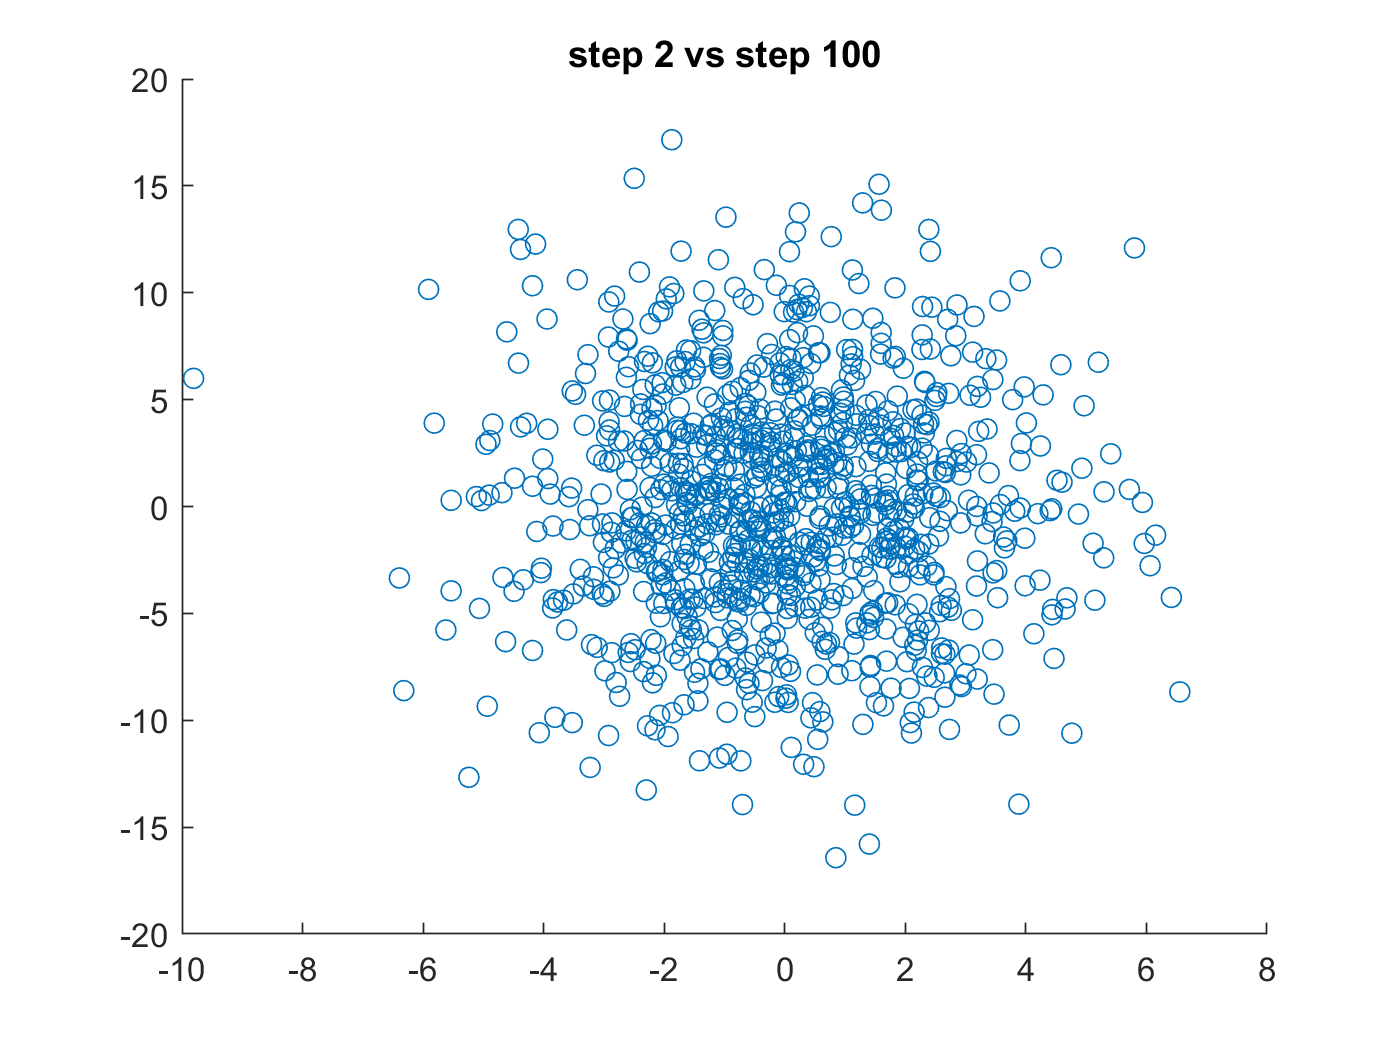

%step 2
%plot(signal(:,500))
figure();
scatter(signal(2,:),signal(100,:))
title('step 2 vs step 100')

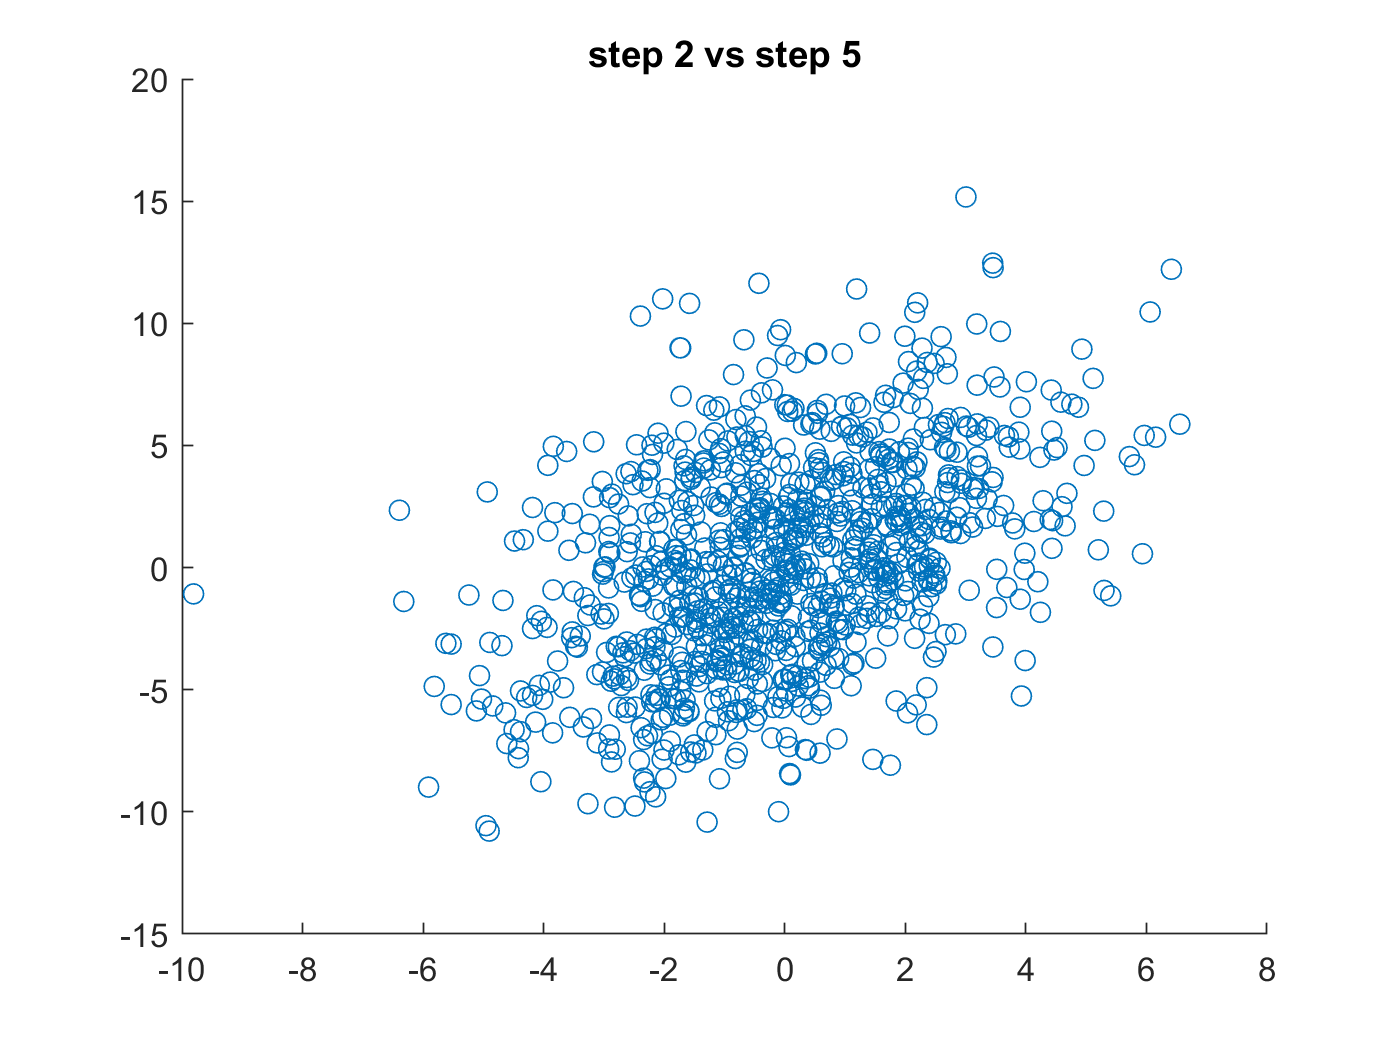

snapnow
%there is no correlation between step 2 and step 100
figure();
scatter(signal(2,:),signal(5,:))
title('step 2 vs step 5')

snapnow

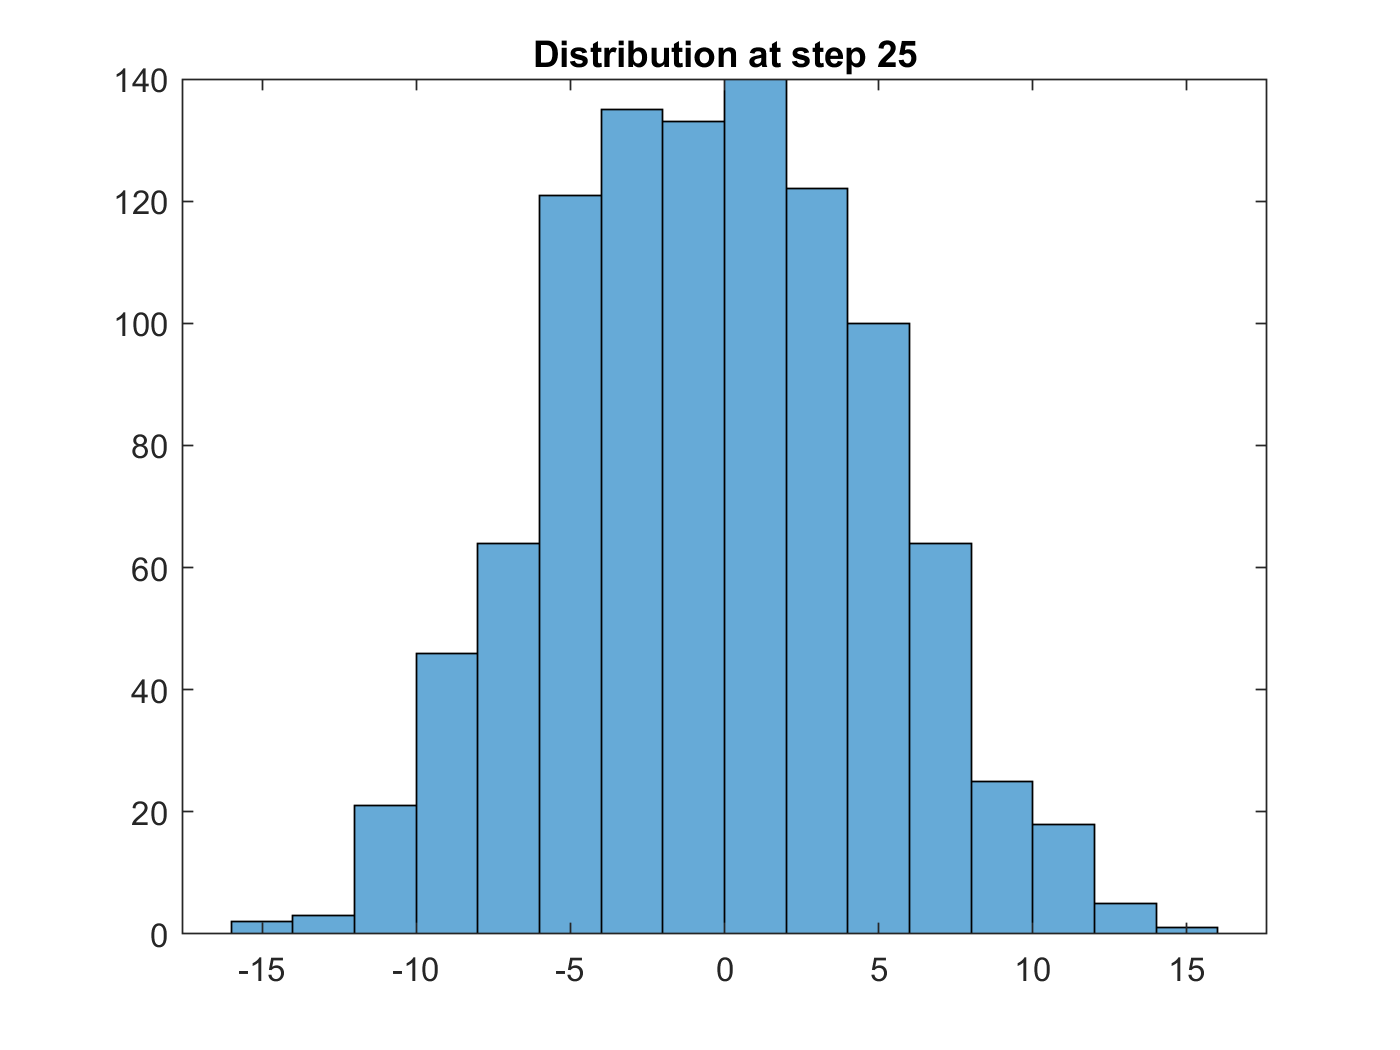

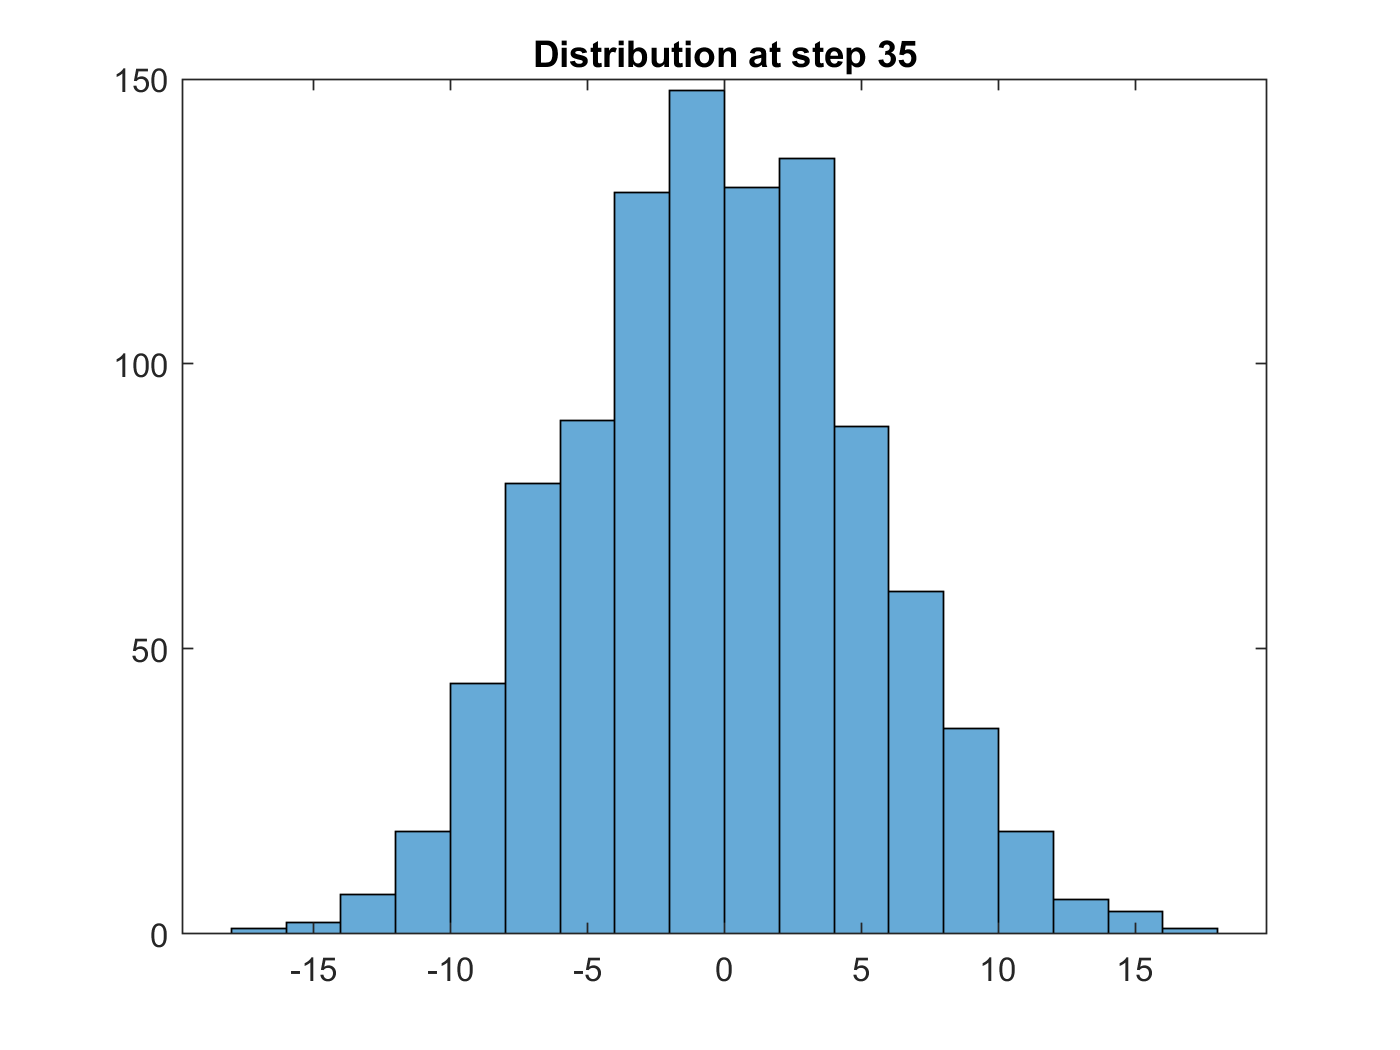

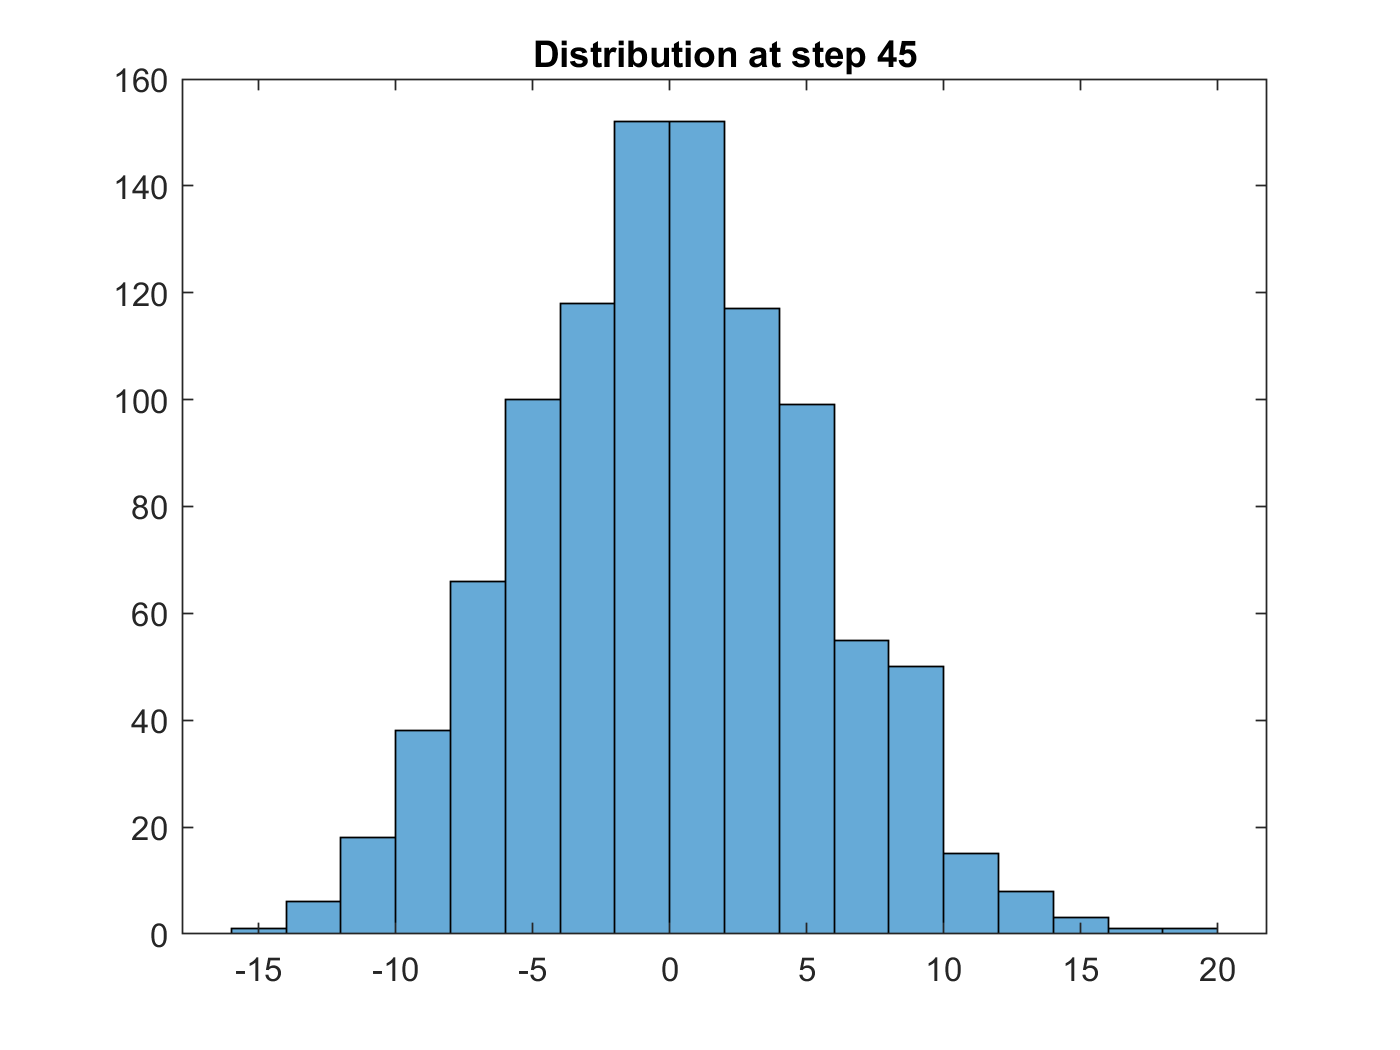

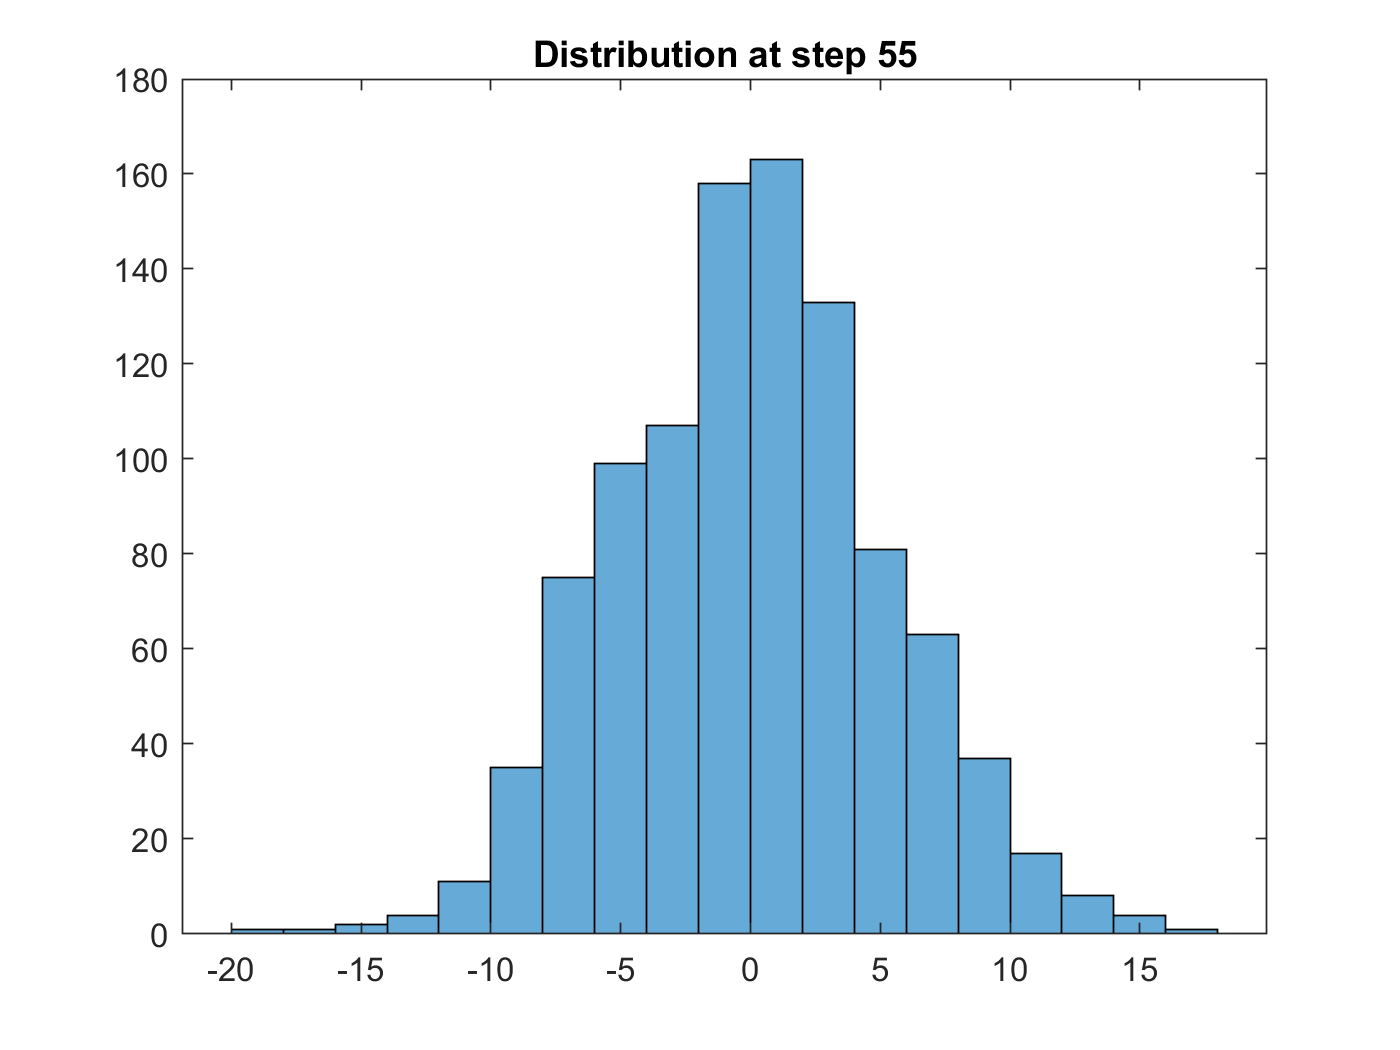

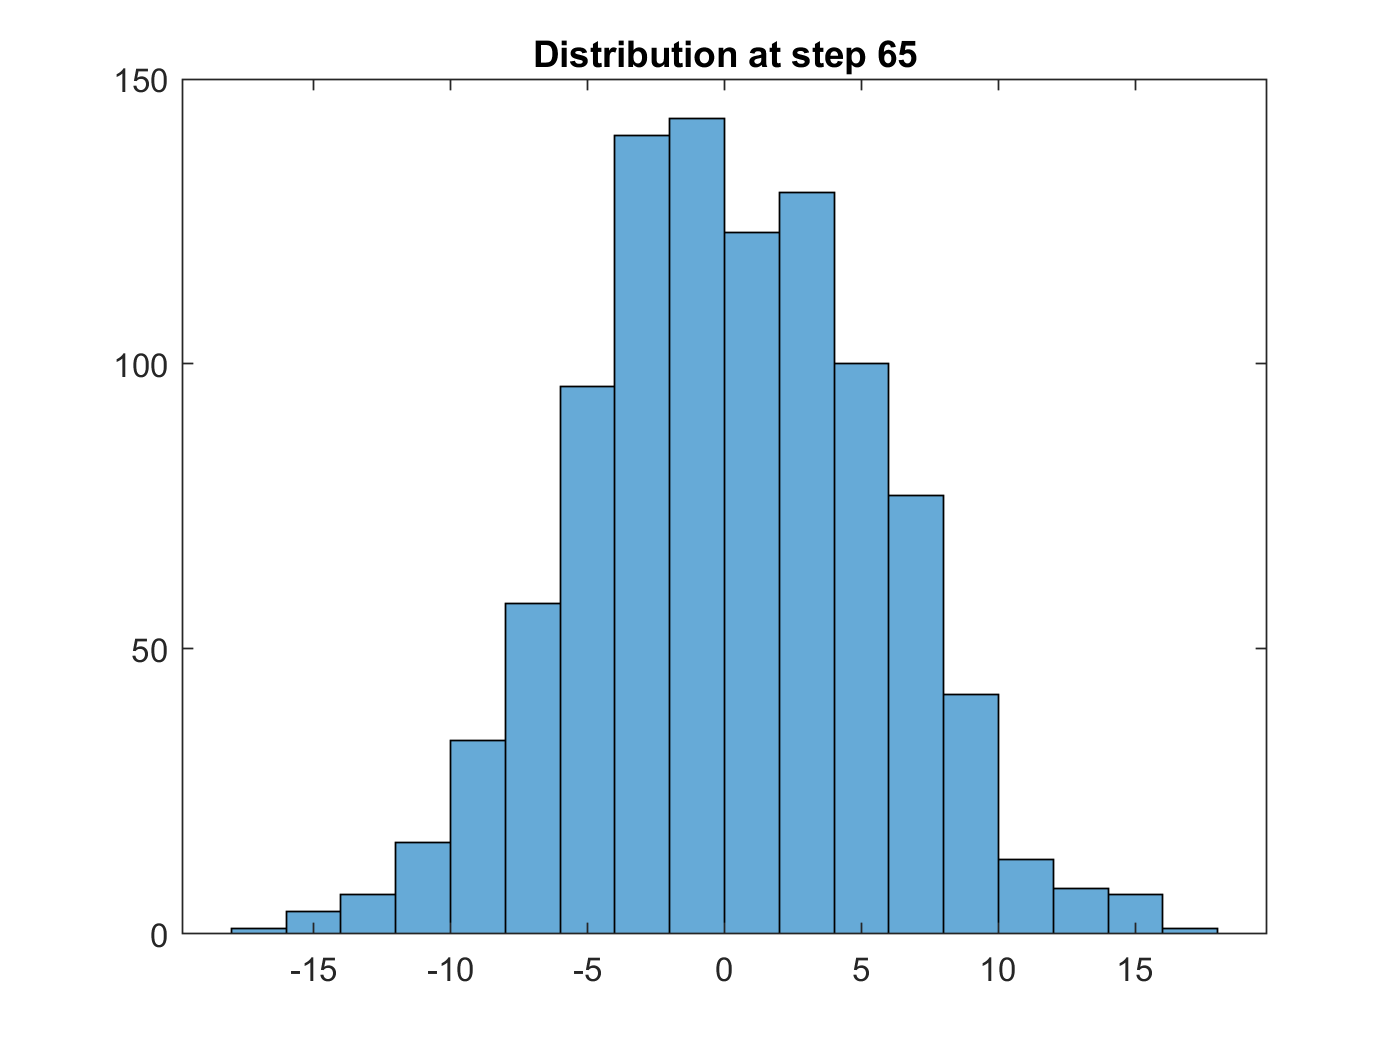

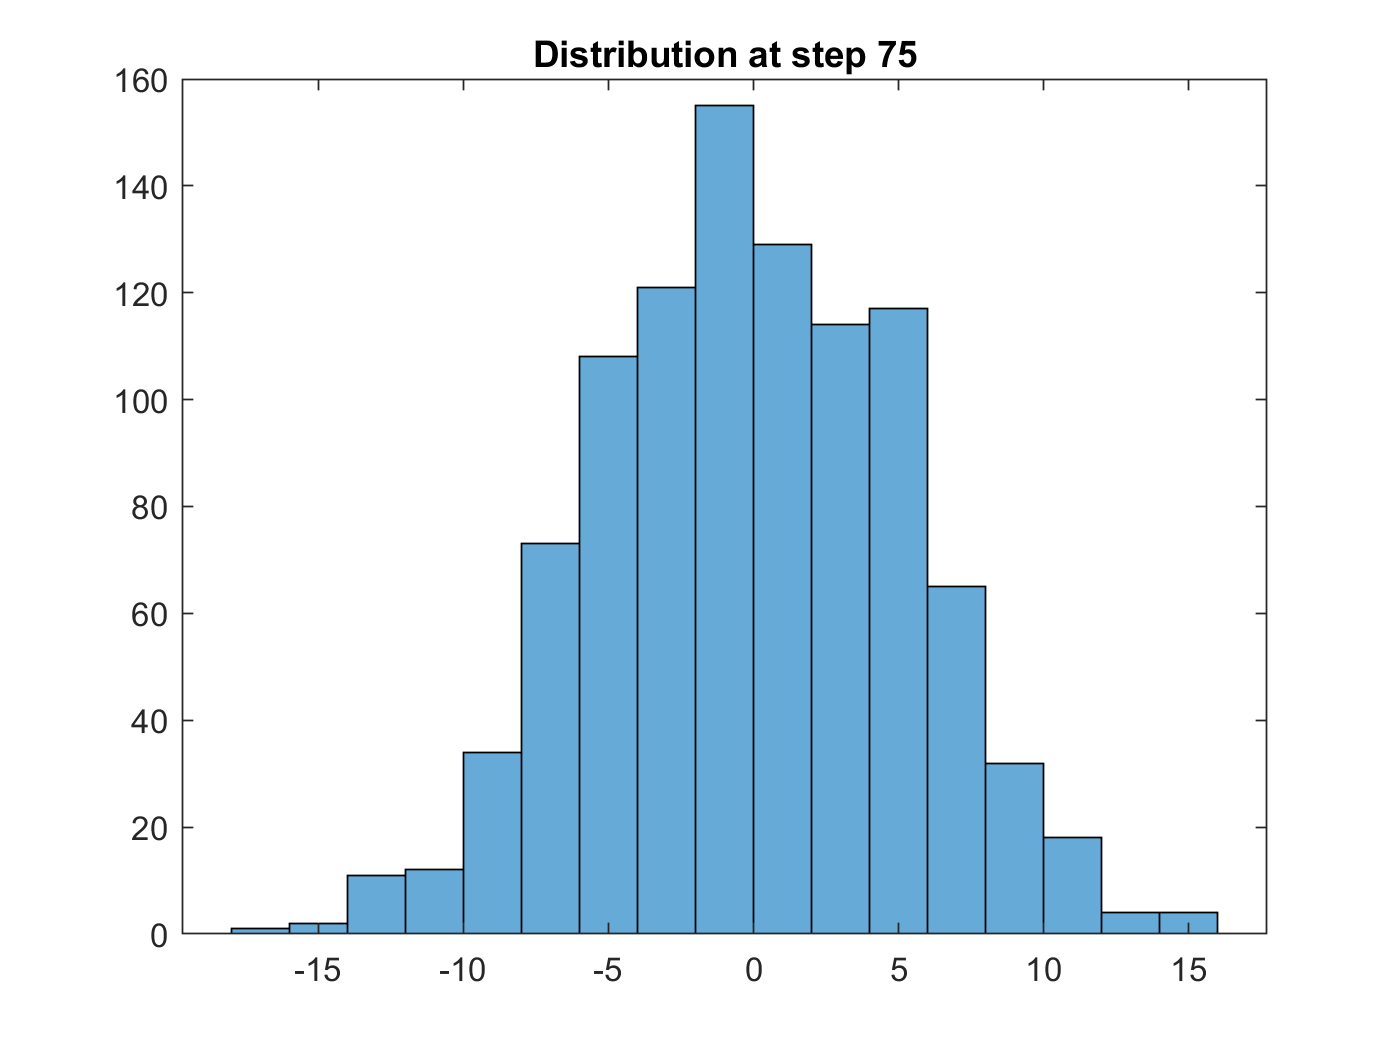

%there is a positive correlation between step 2 and step 5

for i = 25:10:75
    figure();
    histogram(signal(i,:))
    title("Distribution at step " + i)
    snapnow
end

%the distribution at each time step appears gaussian

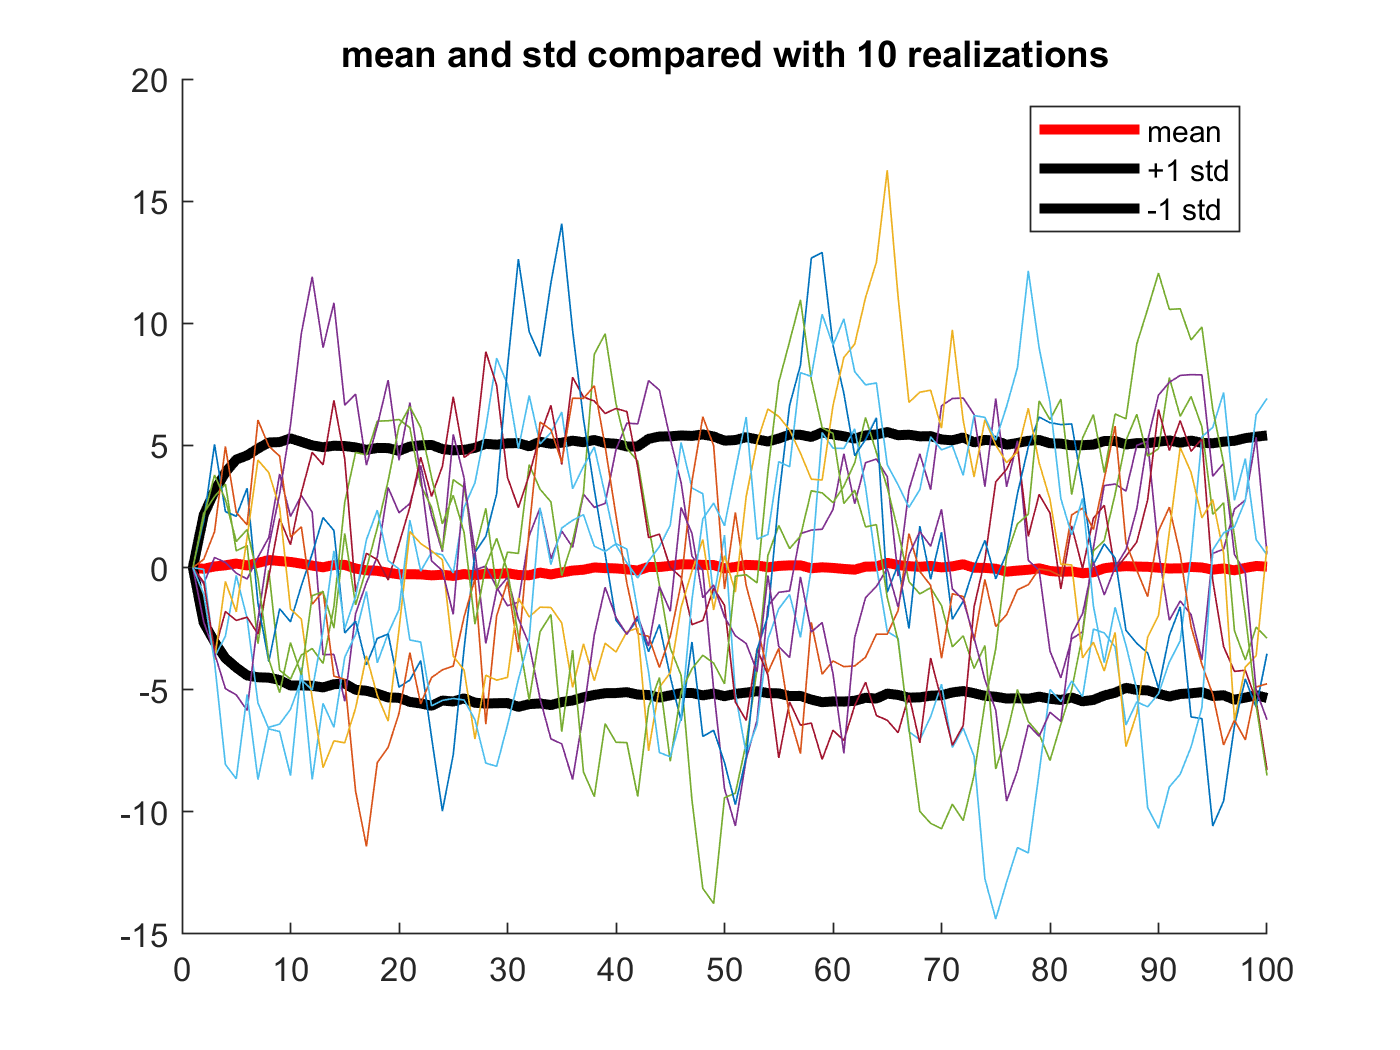

%step 3
sig_mean = zeros(100,1);
sig_std = zeros(100,1);

for i = 1:100
    sig_mean(i,1) = mean(signal(i,:));
    sig_std(i,1) = std(signal(i,:));
end

figure();
hold on
plot(sig_mean,'r','LineWidth',3)
plot(sig_mean + sig_std,'k','LineWidth',3)
plot(sig_mean - sig_std,'k','LineWidth',3)
legend('mean','+1 std','-1 std')
title("mean and std compared with 10 realizations")
for i = 1:10
    plot(signal(:,i),'HandleVisibility','off')
end

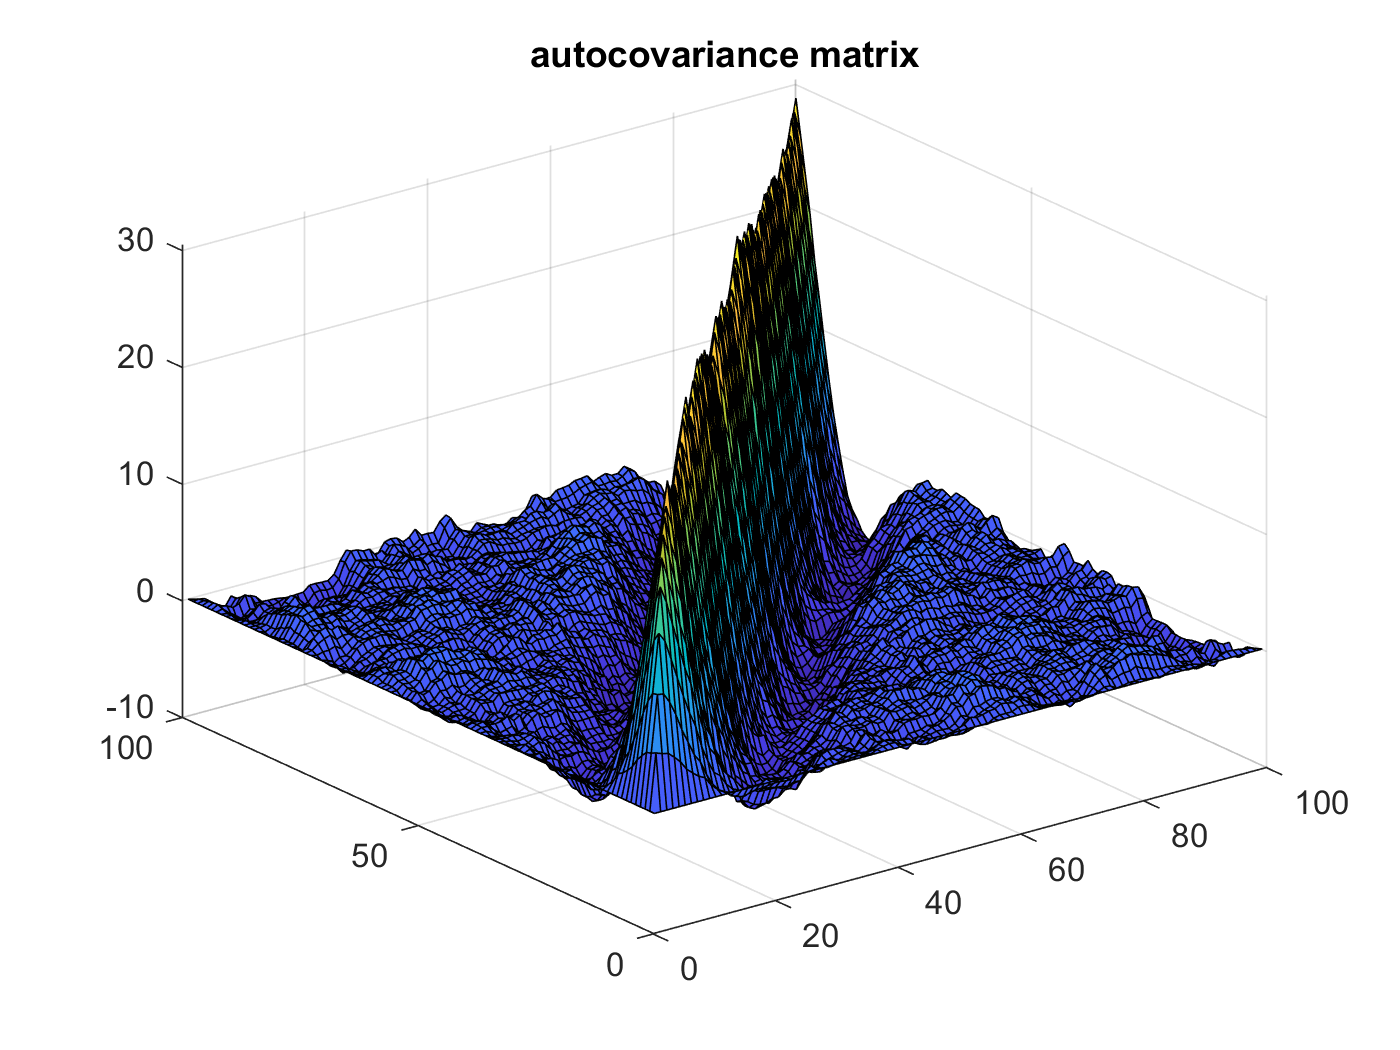

%step 4
cov_matrix = zeros(100);
corr_matrix = zeros(100);
for t1= 1:100
    mx1 = mean(signal(t1,:));
    for t2 = 1:100
        mx2 = mean(signal(t2));
        cov_matrix(t1,t2) = mean((signal(t1,:)-mx1).*(signal(t2,:)-mx2));
        corr_matrix(t1,t2) = mean(signal(t1,:).*signal(t2,:));
    end
end
figure();
surf (cov_matrix)
title("autocovariance matrix")

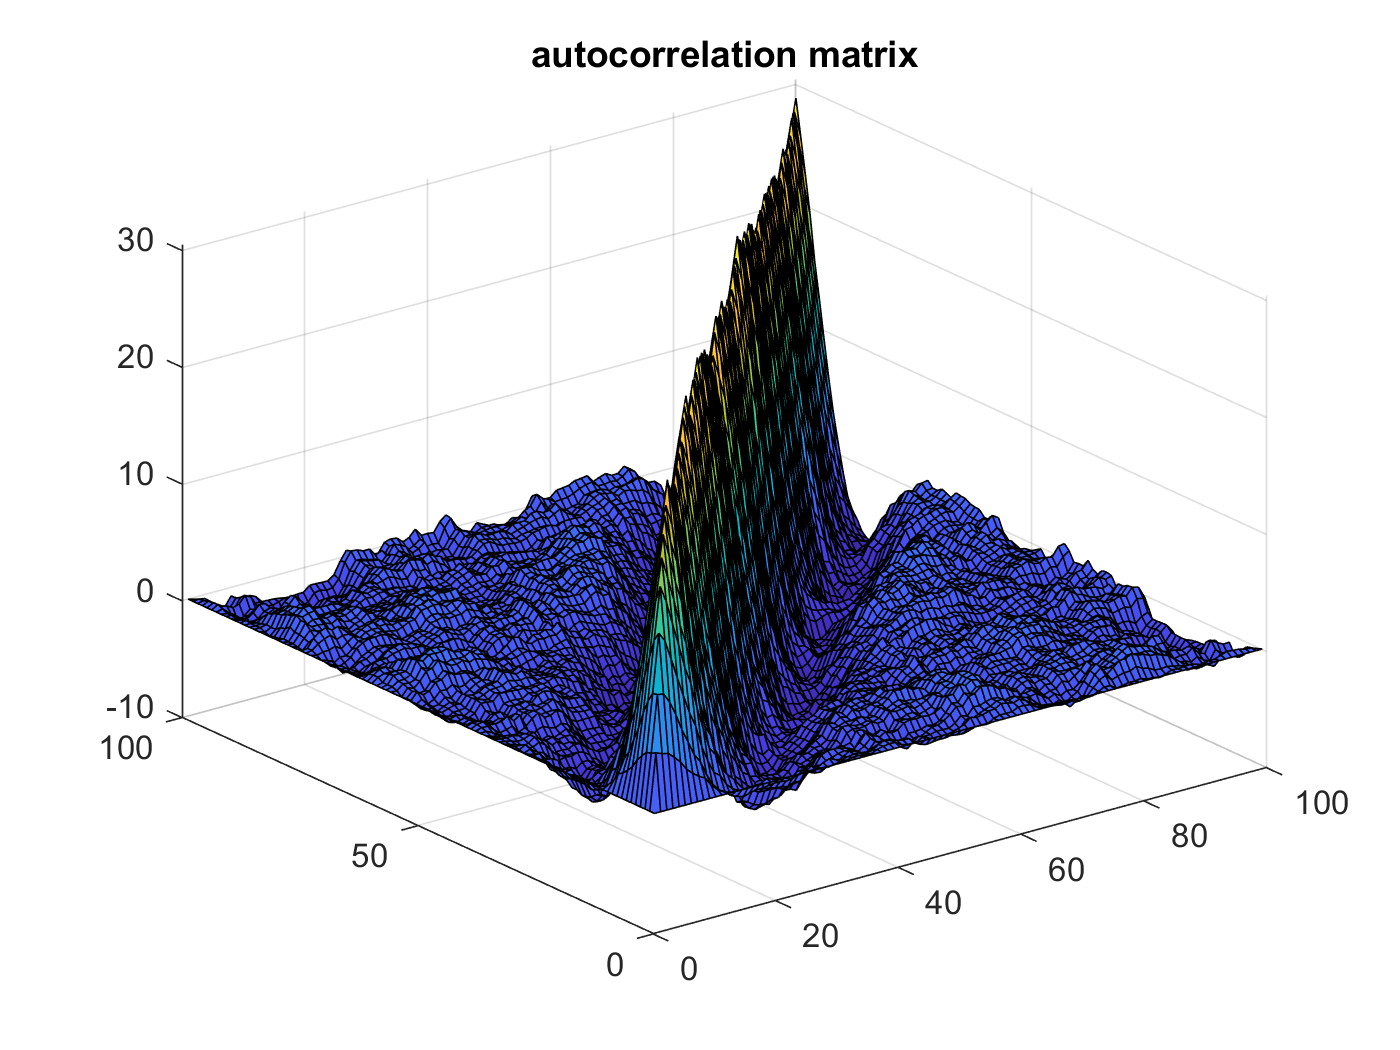


figure();
surf (corr_matrix)
title("autocorrelation matrix")

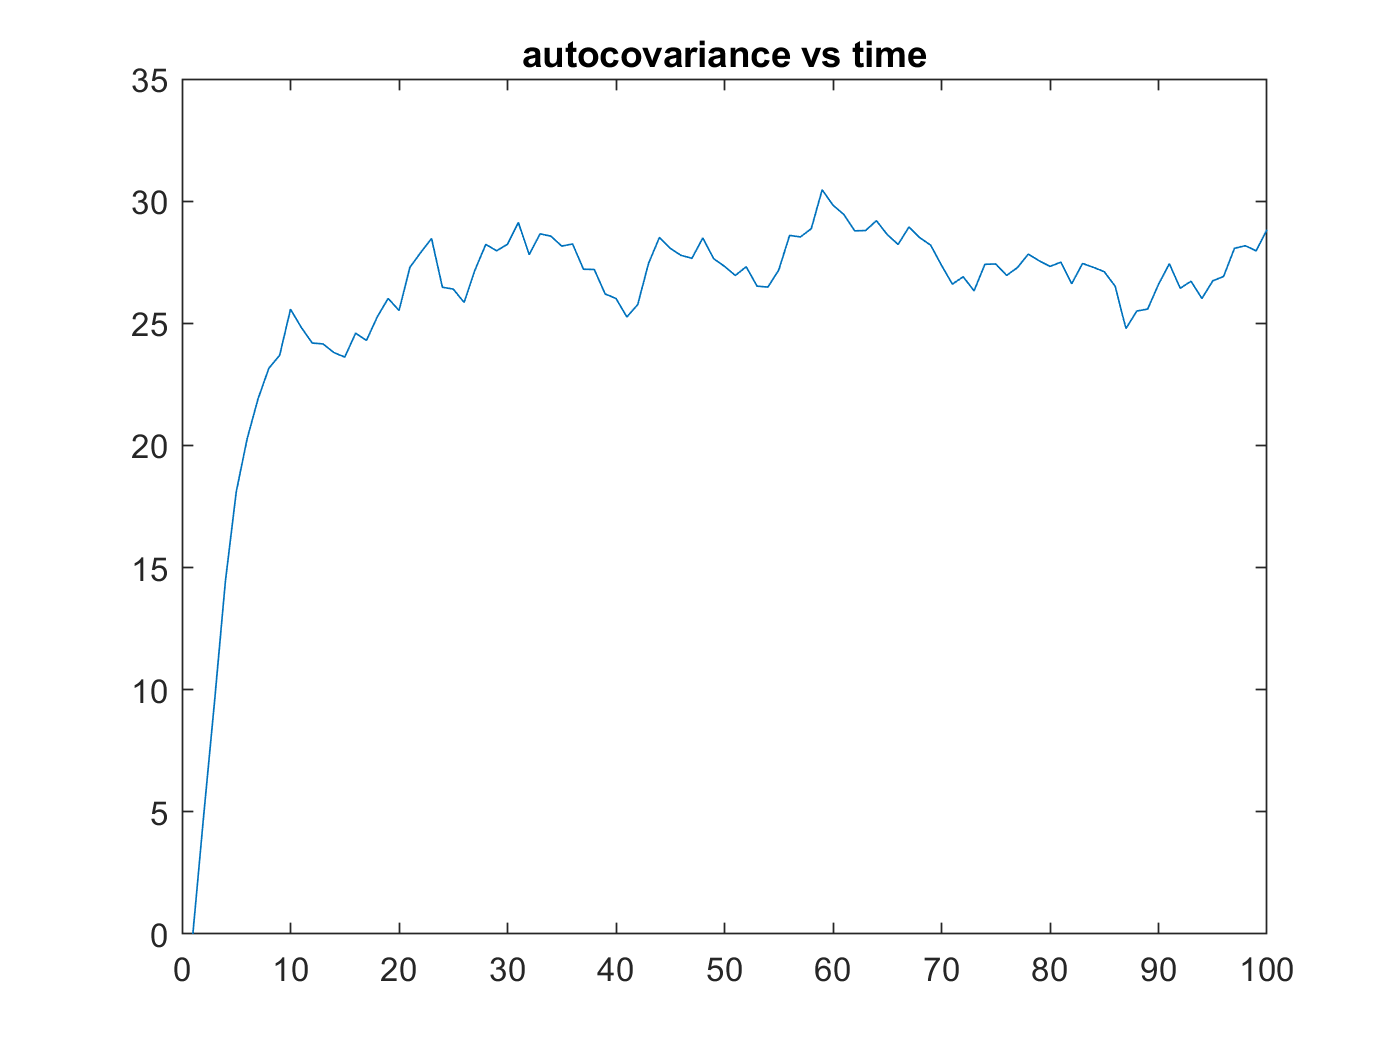

%step 5
cov = zeros(100,1);
corr = zeros(100,1);

for i = 1:100
    cov(i) = cov_matrix(i,i);
    corr(i) = corr_matrix(i,i);
end

figure();
plot(cov)
title("autocovariance vs time")

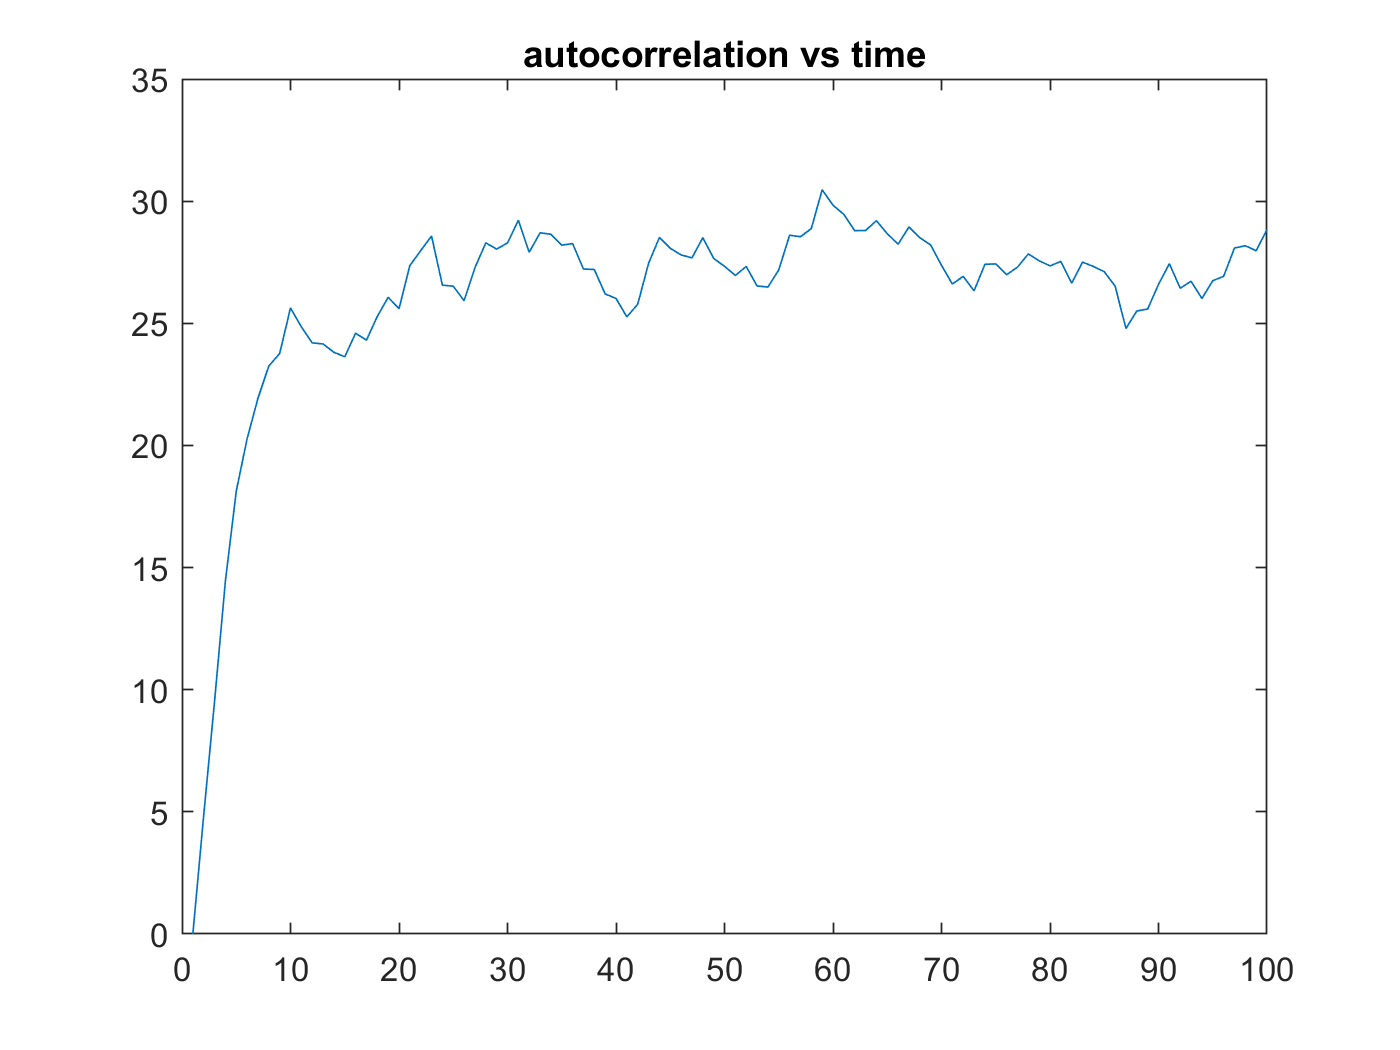

plot(corr)
title("autocorrelation vs time")

The process is not wide-sense stationary because the auto-covariance and auto-correlation are not constant. The process is Gaussian so it is not strict sense stationary because it is not wide sense stationary

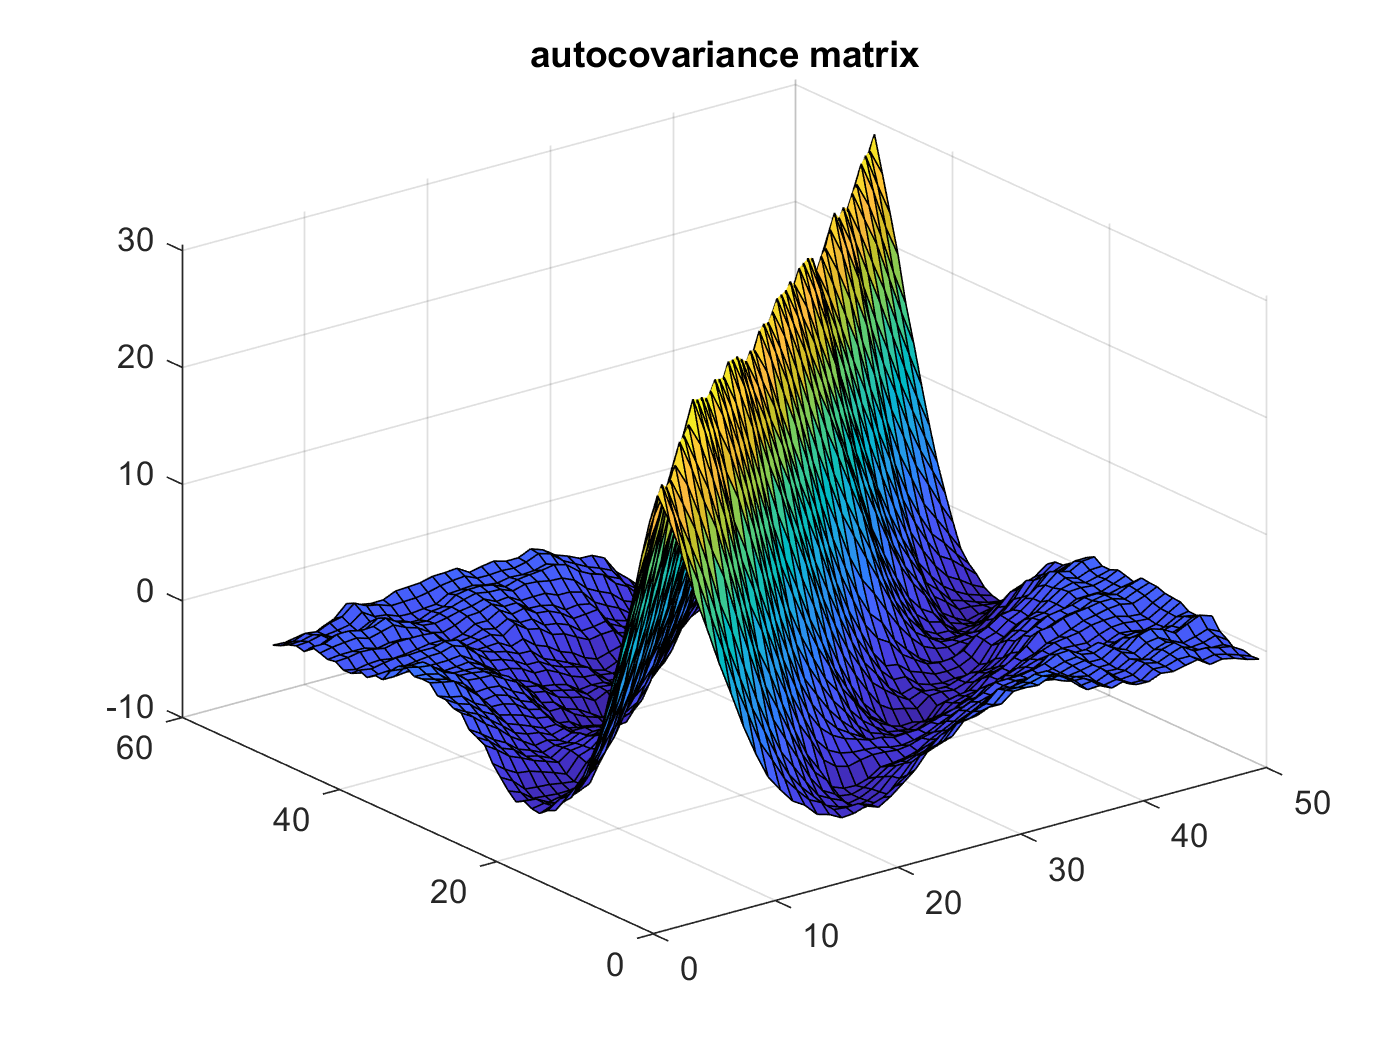

%step 6
signal_SS = signal(51:end,:);
%step 6.4
cov_matrix_SS = zeros(50);
corr_matrix_SS = zeros(50);
for t1= 1:50
    mx1 = mean(signal_SS(t1,:));
    for t2 = 1:50
        mx2 = mean(signal_SS(t2));
        cov_matrix_SS(t1,t2) = mean((signal_SS(t1,:)-mx1).*(signal_SS(t2,:)-mx2));
        corr_matrix_SS(t1,t2) = mean(signal_SS(t1,:).*signal_SS(t2,:));
    end
end
figure();
surf (cov_matrix_SS)
title("autocovariance matrix")

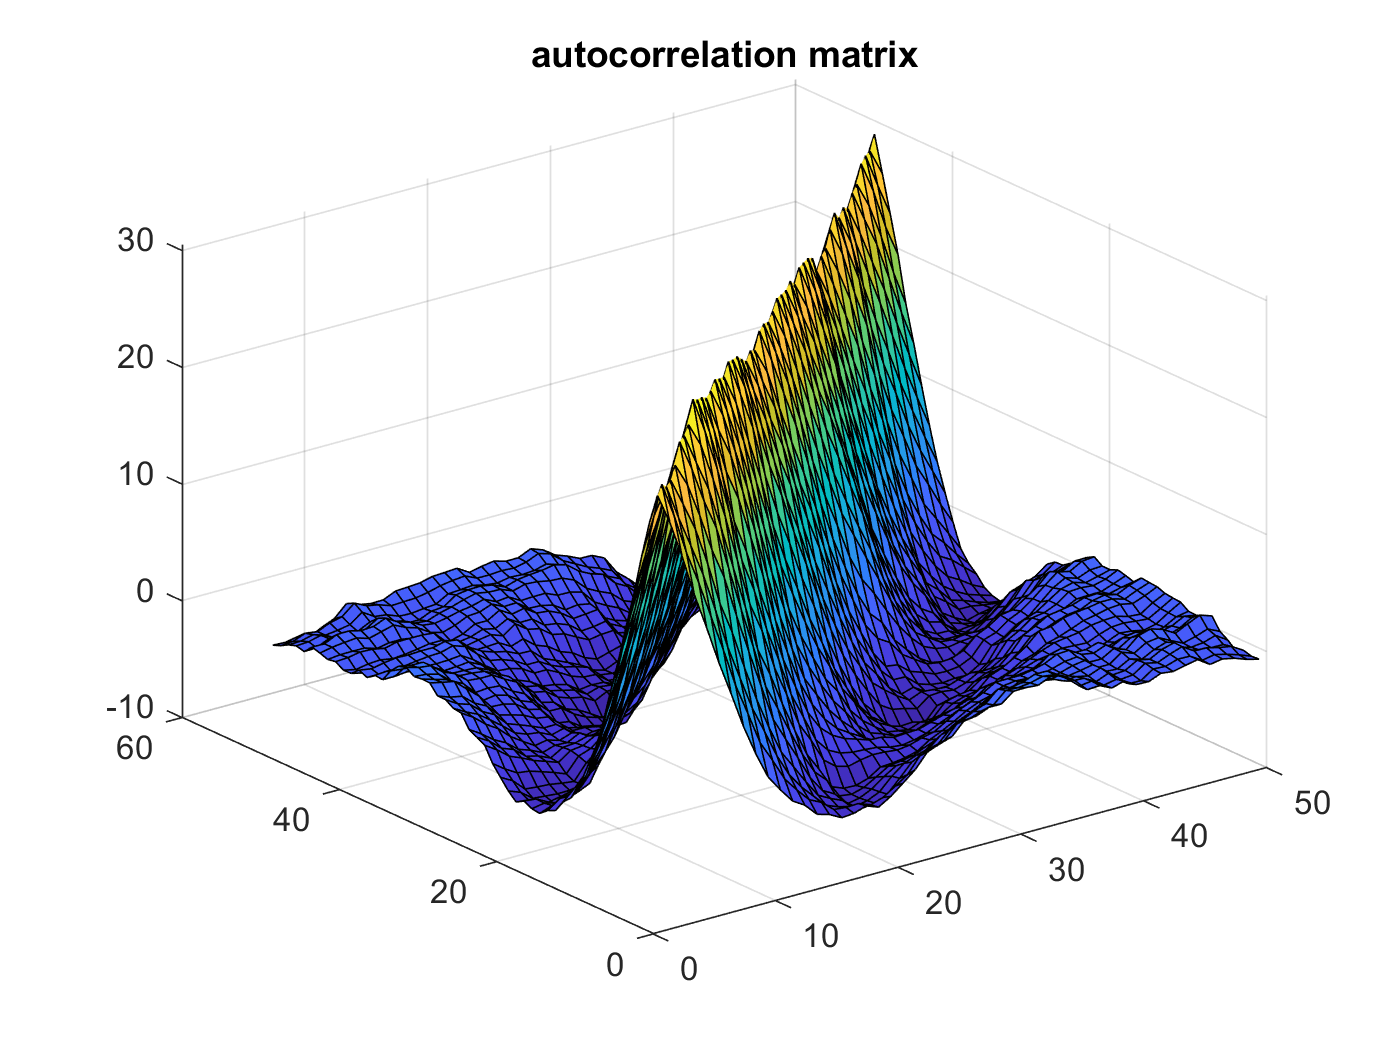

figure();
surf (corr_matrix_SS)
title("autocorrelation matrix")

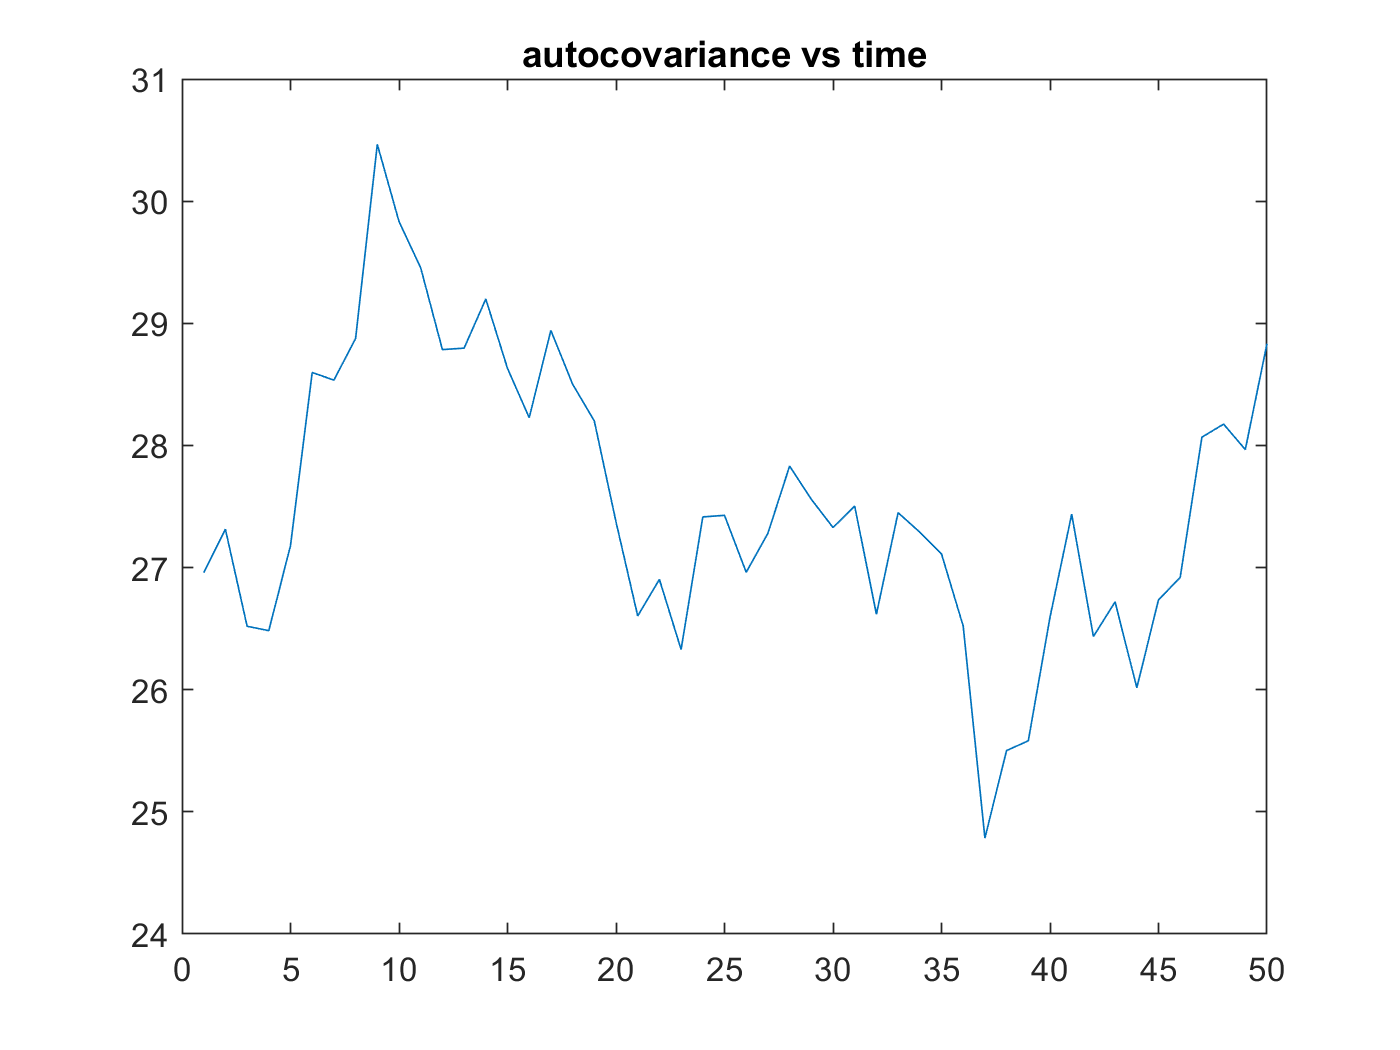

%step 6.5
cov_SS = zeros(50,1);
corr_SS = zeros(50,1);
for i = 1:50
    cov_SS(i) = cov_matrix_SS(i,i);
    corr_SS(i) = corr_matrix_SS(i,i);
end

figure();
plot(cov_SS)
title('autocovariance vs time')

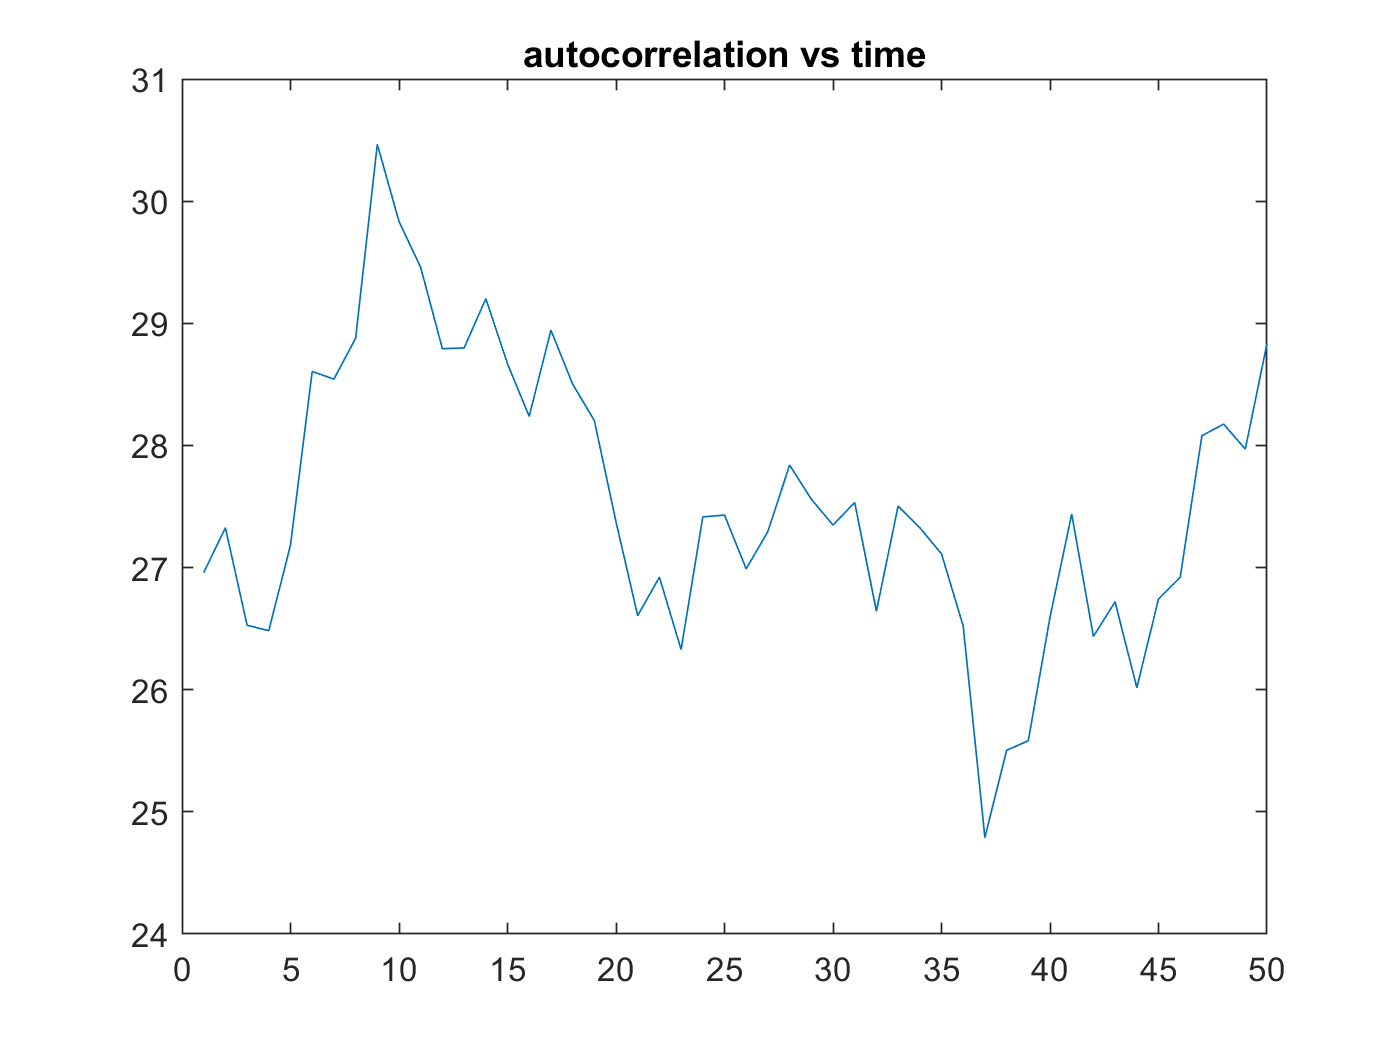

plot(corr_SS)
title('autocorrelation vs time')

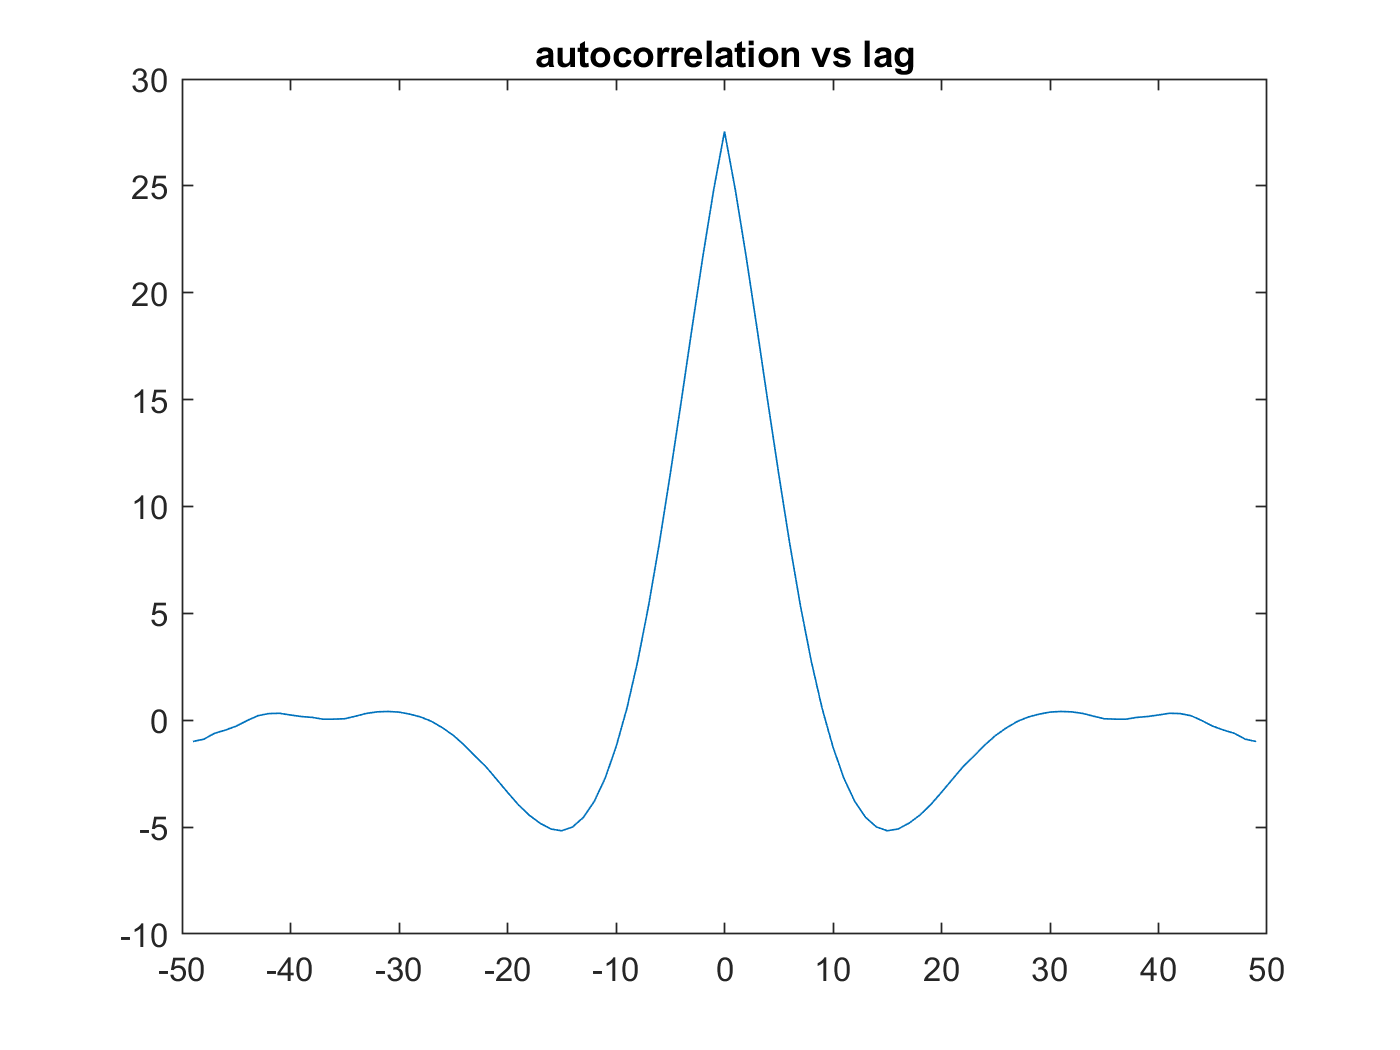

autocorr = zeros(99,1);
for lag = -49:49
    correlations =[];
    for i = 1:(50-abs(lag))
        offset = max(0,lag);
        asdf = corr_matrix_SS(i+offset,i-lag+offset);
        correlations = [correlations asdf];
    end
    autocorr(lag+50) = mean(correlations);
end
figure
plot(-49:49,autocorr)
title('autocorrelation vs lag')

The process is wide sense stationary because the autocovariance and the autocorrelation are roughly constant through time. Because the process is Gaussian, it is also strictly stationary.

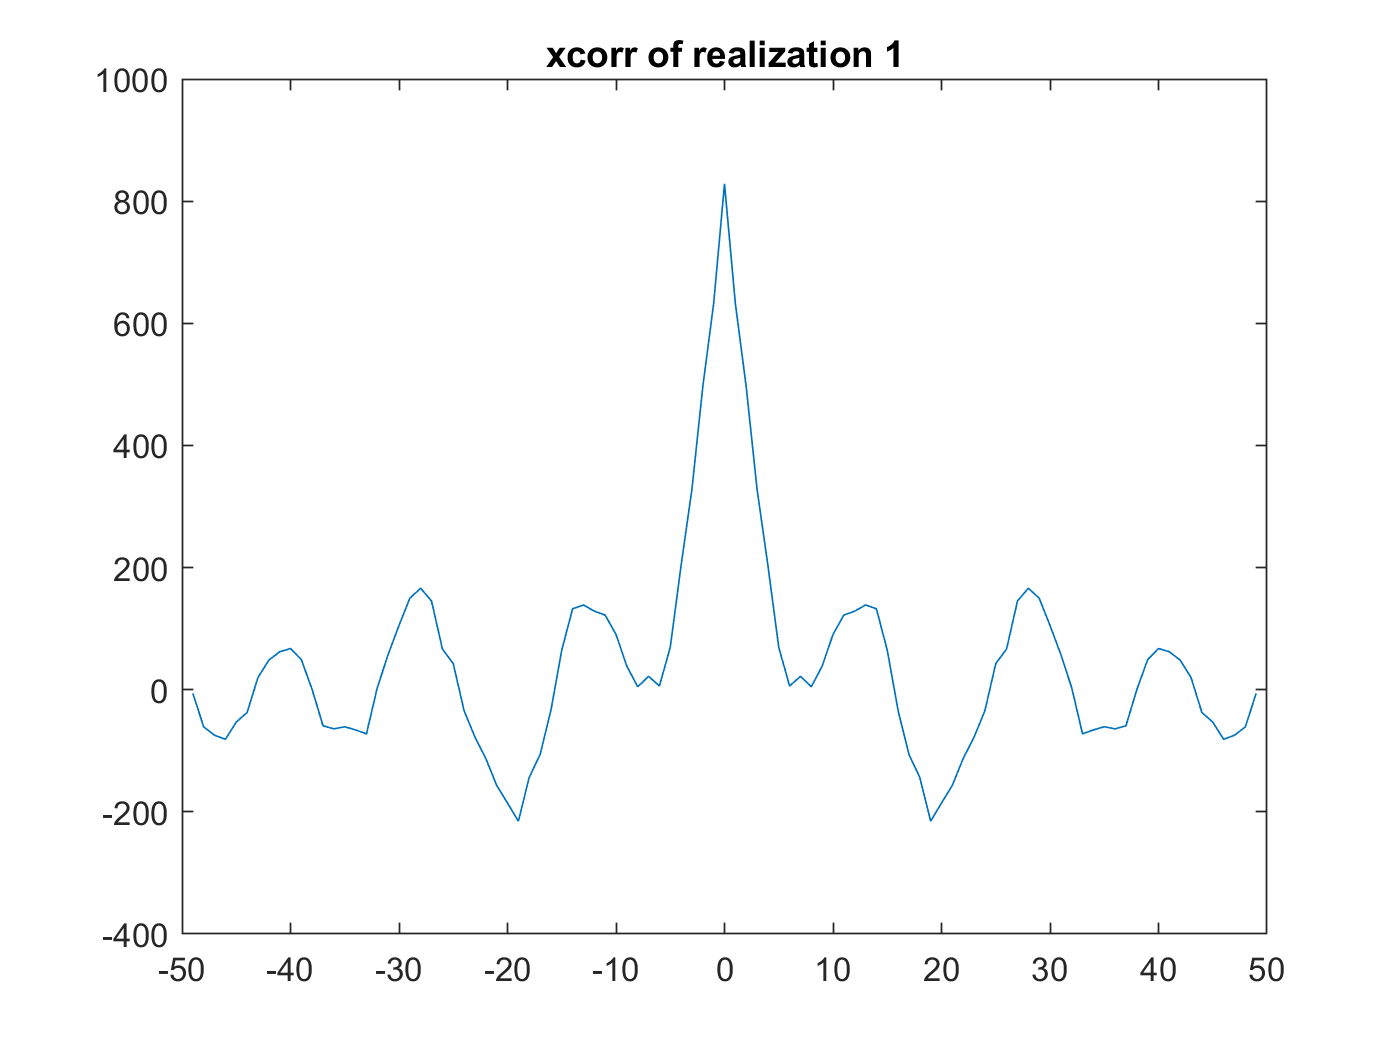

%step 7
figure();
xcorroutput = xcorr(signal_SS(:,1));
plot(-49:49,xcorroutput)
title('xcorr of realization 1')

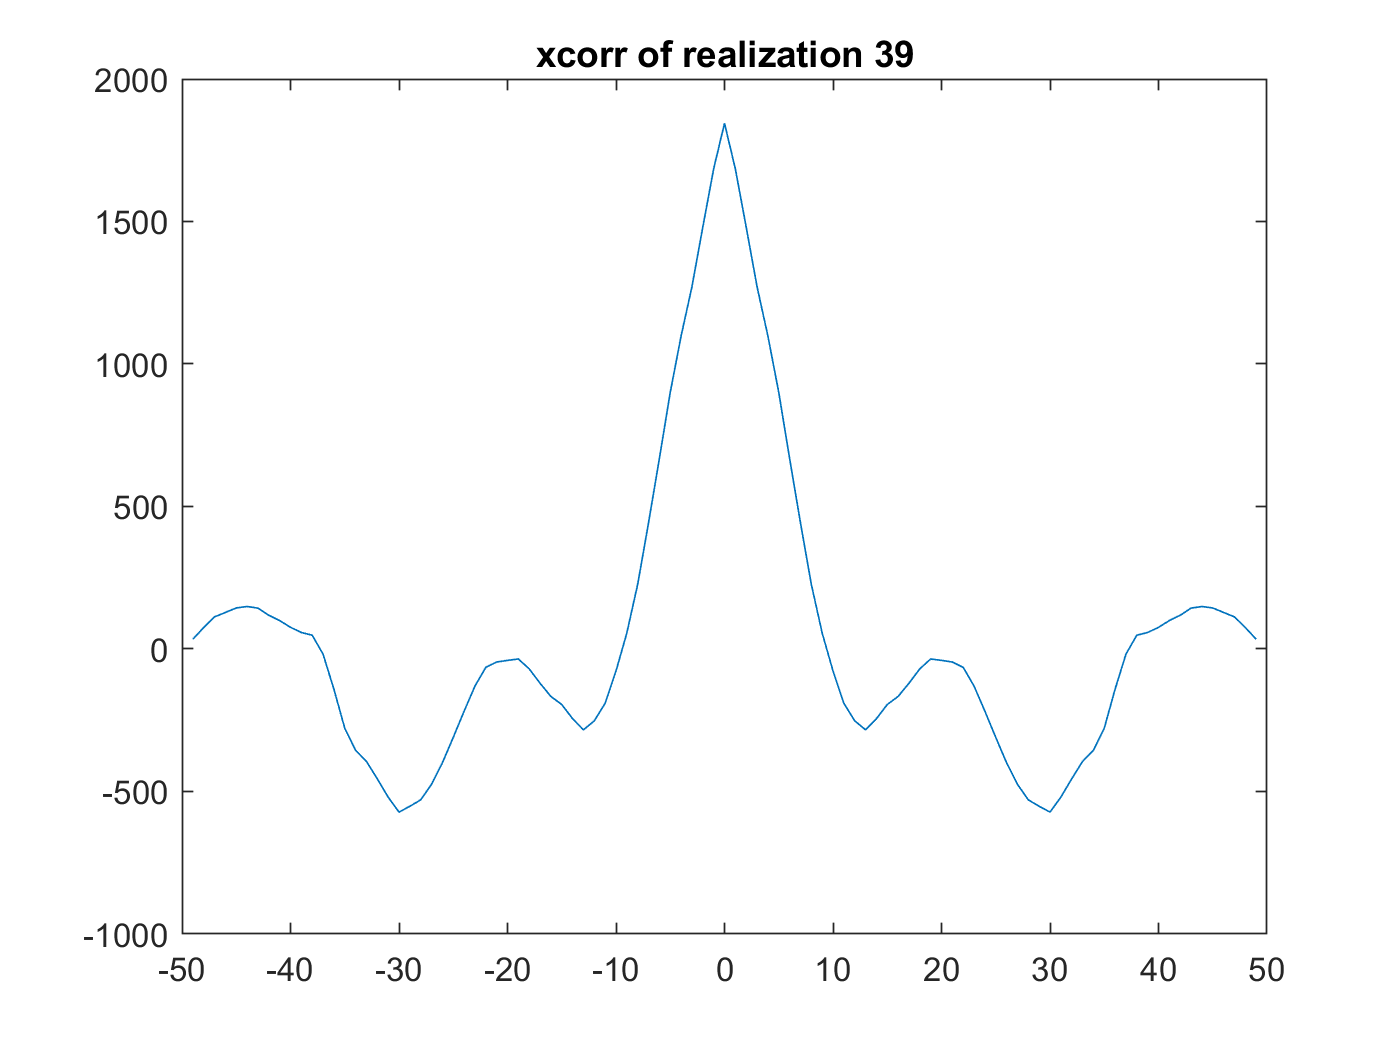

figure();
xcorroutput = xcorr(signal_SS(:,39));
plot(-49:49,xcorroutput)
title('xcorr of realization 39')

The proccess is ergotic because the autocorrelation of all the realizations settles down to 0 at a lag of 30. The time sample of 50 is not long enough for the ergotic assumption to apply because the autocorrelation of a signle realization does not settle to 0 reliably during the sample period. 

The results for xcorr for different samples follows the same general shape but do not settle to 0 autocorrelation at higher lags the same way due to randomness and the low sample time.

Step 8:

A fish can lay a batch of 1000 eggs all under the same anemone. As the fishlings hatch, they will all start to scatter. However, the scattering is limited to within the coral reef because the fish cannot survive outside of it. Except for the one that ends up in a dentist's office and needs to be found.